Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" ([https://www.crcpress.com/9781138589940](https://www.crcpress.com/9781138589940))

# Longitudinal matching (Section 5.4, Figure 5.5)

Volker Ziemann, 211108, CC-BY-SA-4.0

This is essentially the same simulation as `LargeAmplitudeOscillations.mlx`, only the initial distribution is changed and the integration time increased to 100*Ts. You can observe how the particles initially inside a square box eventually fill a circular region that essentially looks unchanged henceforth.

As before, the simulation is based on pendulum_tracker(), but changes the input distribution and the duration of the integration and increases the number of particles `N`.

clear all; close all
N=500;            % number of particles
Omegas=0.25;      % synchrotron frequency
Ts=2*pi/Omegas;   % the time for one small-amplitude oscillation

Here I set` dt `to` dt=Ts*100`.

dt=100*Ts;                          % integration time=duration

and define the input distribution to be centered and wider in the horizontal (phase) direction. 

x0=[0.0,0.0];     % center of initial (green) distribution
dx=[2.0,0.1];     % spread of initial (green) distribution

Like before, we defne the range of phases, plot the separatrix, and annotate the axes

phi=-pi:0.01:pi;  % range of angles
separatrix=2*Omegas*cos(0.5*phi);     % plot the separatrix
hold off; plot(phi,separatrix,'k',phi,-separatrix,'k')
axis([-pi,pi,-0.67,0.67]); hold on; pause(0.001)
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
  'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})             % xlabels
text(-2.8,-0.57,['After ',num2str(dt/Ts),' T_s'],'fontsize',16)  % duration

and loop over the particles, where we make a green dot at the starting coordinates and a black dot at the final coordinates.

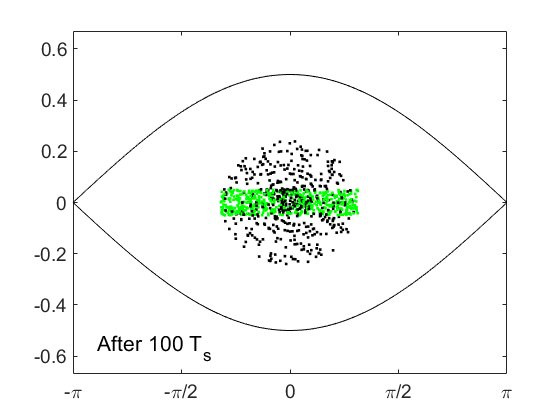

for k=1:N   % loop over particles
  x=x0+(rand(1,2)-0.5).*dx;  
  plot(x(1),x(2),'g.');
  x1=pendulumtracker(x,Omegas,dt); 
  plot(x1(1),x1(2),'k.');
  pause(0.001)
end

And now you can go back to set `dt=3*Ts` in order to generate the plot on the left-hand side in Figure 5.5 in the book.

That all, folks!

## Appendix

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude synchrotron frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54.

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2;      % just after eq. 5.45
k=sqrt(k2);
if (x(1)>pi) x(1)=x(1)-2*pi; end            % map back into range [-pi,pi]
if (x(1)<-pi) x(1)=x(1)+2*pi; end           
s=1; if (x(1)<0) s=-s; x(1)=-x(1); end      % keep track of quadrant
s1=1; if (x(2)<0) s1=-s1; end
if (k>1)   % outside the separatrix
  kelf=ellipke(1/k2);                                % faster
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*ellipticF(0.5*x(1),1/k2);
  % tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);     % faster
  [sn,cn,dn]=ellipj(tmp,1/k2);    
  if (abs(tmp) > kelf) sn=-sn; end
  xout(1)=2*asin(sn);                % eq. 5.52
  xout(2)=2*s1*omega*k*dn;
else       % inside the separatrix
  trev=4*ellipke(k2)/omega;                          % faster
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*ellipticF(z0,k2);
  % tmp=s1*omega*t0+s*elliptic12(z0,k2);               % faster
  [sn,cn,dn]=ellipj(tmp,k2);
  xout(1)=2*asin(k*sn);               % eq. 5.54
  xout(2)=2*s1*omega*k*cn;
end
end

This version uses the built-in functionand `ellipticF()`, which is rather slow. They should be replaced by `elliptic12()` from the package elliptic from[  ](https://github.com/moiseevigor/elliptic)[https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) , which speeds up the simulation dramatically.